clear all
cover = readtable('covtype.csv'); %%581012 observations
%%turn into matrix 
%%randomly select 20k obs
rand_index = randi(581012,20000,1); 
covermat = cover{:,:}(rand_index,:);
varNames = cover.Properties.VariableNames;
%%get labels
target = covermat(:,55);
%%numerical features
cov_numerical = covermat(:,1:10);
%%mean 0, sd 1
cov_normal = normalize(cov_numerical);
%%unique identities
uniqueTarget = unique(target);

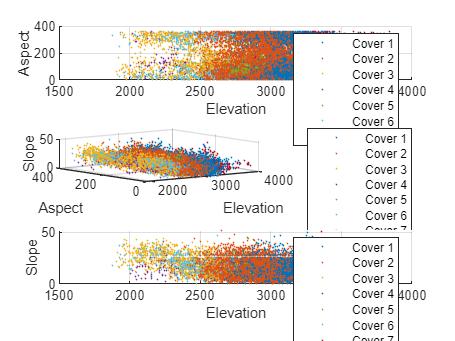

%%Aspect, Elevation, and Slope Visualization
colors = {[0 0.4470 0.7410],[0.8500 0.3250 0.0980],[0.9290 0.6940 0.1250],[0.4940 0.1840 0.5560],[0.4660 0.6740 0.1880],[0.3010 0.7450 0.9330],[0.6350 0.0780 0.1840]};
elevation = cov_numerical(:,1);
aspect = cov_numerical(:,2);
slope = cov_numerical(:,3);
figure(2)
subplot(3,1,1)
view(2)
xlabel('Elevation'); ylabel('Aspect'); zlabel('Slope');
grid on
hold on 
for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k); 
      plot3(elevation(ind),aspect(ind),slope(ind),'.','color',cell2mat(colors(k)),'markersize',1); 
      
end
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

subplot(3,1,2)

view(3)
xlabel('Elevation'); ylabel('Aspect'); zlabel('Slope');
grid on
hold on 
for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k); 
      plot3(elevation(ind),aspect(ind),slope(ind),'.','color',cell2mat(colors(k)),'markersize',1); 
      hold on;
      
end
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

subplot(3,1,3)
view(2)
xlabel('Elevation'); ylabel('Slope'); zlabel('Aspect');
grid on
hold on

for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k); 
      plot3(elevation(ind),slope(ind),aspect(ind),'.','color',cell2mat(colors(k)),'markersize',1); 
      
end
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

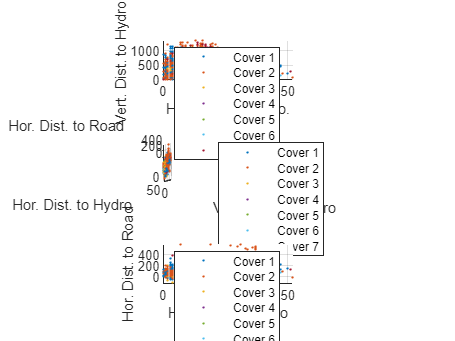

%Horizontal Distances and Vertical Distances Visualization

hordist1 = cov_numerical(:,3);
vdist = cov_numerical(:,4);
hordist2 = cov_numerical(:,5);

figure(3)
subplot(3,1,1)
view(2)
xlabel('Hor. Dist. to Hydro.'); ylabel('Vert. Dist. to Hydro.'); zlabel('Hor. Dist. to Road.');
grid on
hold on 
for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k); 
      plot3(hordist1(ind),vdist(ind),hordist2(ind),'.','color',cell2mat(colors(k)),'markersize',4); 
      
end
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

subplot(3,1,2)

view(80,30)
xlabel('Hor. Dist. to Hydro'); ylabel('Vert. Dist. to Hydro'); zlabel('Hor. Dist. to Road');
grid on
hold on 
for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k); 
      plot3(hordist1(ind),vdist(ind),hordist2(ind),'.','color',cell2mat(colors(k)),'markersize',4); 
      
end
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

subplot(3,1,3)
view(2)
xlabel('Hor. Dist. to Hydro'); ylabel('Hor. Dist. to Road'); zlabel('Vert. Dist. to Hydro');
grid on
hold on

for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k); 
      plot3(hordist1(ind),hordist2(ind),vdist(ind),'.','color',cell2mat(colors(k)),'markersize',4); 
      
end
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

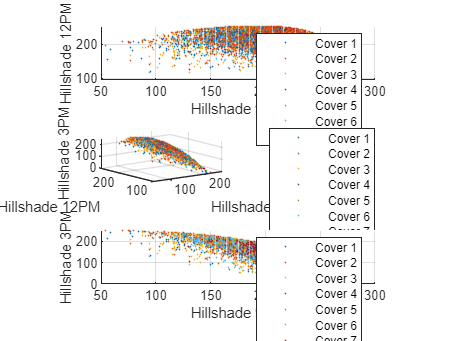

%%Hillshade Visualization 

hillshade9 = cov_numerical(:,7);
hillshade12 = cov_numerical(:,8);
hillshade3 = cov_numerical(:,9);

figure(4)
subplot(3,1,1)
view(2)
xlabel('Hillshade 9AM'); ylabel('Hillshade 12PM'); zlabel('Hillshade 3PM');
grid on
hold on 
for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k); 
      plot3(hillshade9(ind),hillshade12(ind),hillshade3(ind),'.','color',cell2mat(colors(k)),'markersize',3); 
      
end
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

subplot(3,1,2)

view(3)
xlabel('Hillshade 9AM'); ylabel('Hillshade 12PM'); zlabel('Hillshade 3PM');
grid on
hold on 
for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k); 
      plot3(hillshade9(ind),hillshade12(ind),hillshade3(ind),'.','color',cell2mat(colors(k)),'markersize',3); 
      
end
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

subplot(3,1,3)
view(2)
xlabel('Hillshade 9AM'); ylabel('Hillshade 3PM'); zlabel('Vert. Dist. to Hydro');
grid on
hold on

for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k); 
      plot3(hillshade9(ind),hillshade3(ind),hillshade9(ind),'.','color',cell2mat(colors(k)),'markersize',3); 
      
end
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

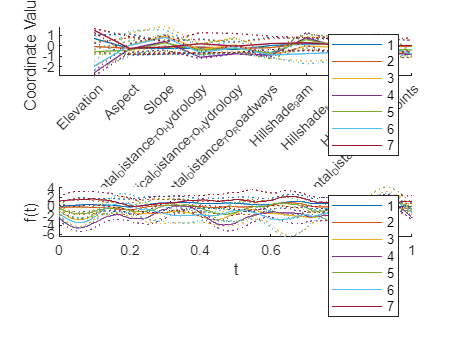

%%interesting plots

figure(5)
subplot(2,1,1)
parallelcoords(cov_numerical, 'group',target, 'standardize','on', 'labels',varNames(1:10),'quantile',.25)
subplot(2,1,2)
andrewsplot(cov_numerical, 'group',target, 'standardize','on','quantile', .25)

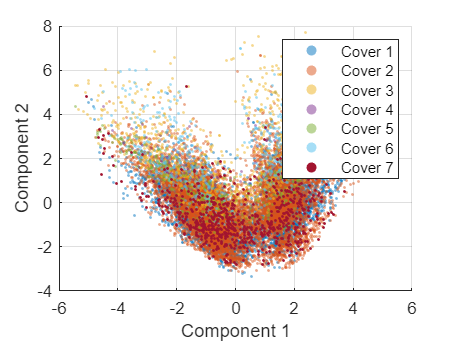

%%PCA
%% 25% first component, 21% second component, 17% third component, 10% fourth component, 22% rest of components 
[coeff,score,latent,tsquared,explained,mu] = pca(cov_normal); 

%%obtain first three maximum-var directions
pca1 = score(:,1);
pca2 = score(:,2);
pca3 = score(:,3);

%%Visualization Below
figure(6)

%%2D Visualization
xlabel('Component 1'); ylabel('Component 2');
grid on
hold on 
for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k); 
      sz = 3;
      alpha(0.5)
      scatter(pca1(ind),pca2(ind), sz, cell2mat(colors(k)), 'filled'); 
      
end
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

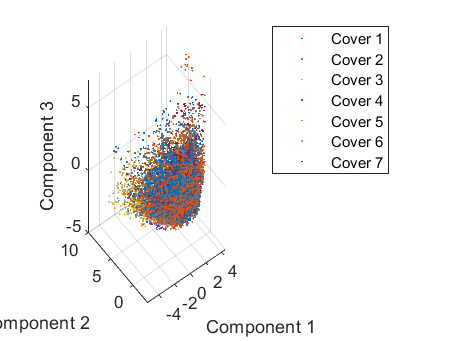


%%3D Visualization
figure(7)
xlabel('Component 1'); ylabel('Component 2'); zlabel('Component 3');
grid on
hold on 
view(3)

for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k);
      alpha(0.5)
      plot3(pca1(ind),pca2(ind), pca3(ind), '.', 'color', cell2mat(colors(k)), 'markersize',1); 
      
      
end
hold off
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

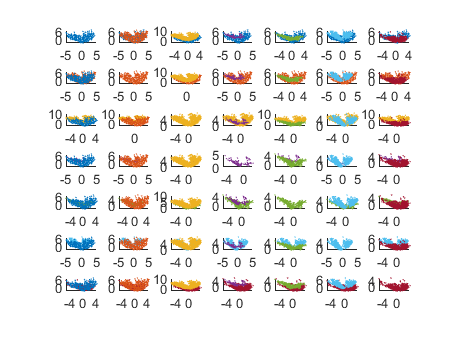


%%suggests data is not able to project well using PCA for all 7 covertypes, does it differentiate well for two at a time?

%%Pairwise Visualization
figure(8)
grid on
hold on

counter = 1;
for k = 1:(length(uniqueTarget))
    ind1 = target ==uniqueTarget(k);
    for j = 1:length(uniqueTarget)
      subplot(7,7,counter);
      ind2 = target == uniqueTarget(j);
      alpha(0.2)
      sz =1;
      scatter(pca1(ind1),pca2(ind1), sz, cell2mat(colors(k)), 'filled');
      hold on
      scatter(pca1(ind2), pca2(ind2), sz, cell2mat(colors(j)), 'filled')
      hold off
      counter = counter +1;
    end
      
end

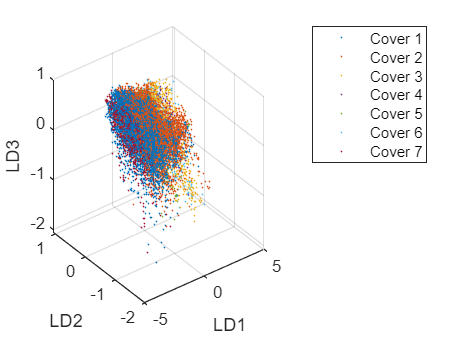

%%LDA 

%%Initialize empty cells/mats for
%%within matrix, centroid matrix
within = cell(7, 1);
centroid_mat = []; %%bad for memory, sorry
length_vec = []; %%bad for memory, sorry

%%Saving centroids, lengths, and within-scatter mats
for k = 1:length(uniqueTarget)
    ind = target ==uniqueTarget(k); 
    mat = cov_normal(ind,:);
    length_vec(k) = size(mat,1);
    group_mean = sum(mat,1)/size(mat,1);
    centroid_mat(:,k) = group_mean;
    scatter_mat = (bsxfun(@minus,mat,group_mean))'*(bsxfun(@minus,mat,group_mean));
    within{k} = scatter_mat;
end

%%Compute within-scatter matrix
sw = within{1} + within{2} + within{3} + within{4} + within{5} + within{6} + within{7};
inv(sw); %%invertible
%%Compute global centroid
global_centroid = sum(cov_normal,1)/size(cov_normal,1);
%%Class centroids minus global centroid
dif_mat = centroid_mat - repmat(global_centroid,7,1)';
%%sqrt(n_i) * (m_i - m_global)
Mtild = (sqrt(length_vec).*dif_mat)';
%%between class
sb = Mtild'*Mtild;
%%Get right generalized eigenvectors
[V,D,W] = eig(sb,sw); 
%%Get column norms
norms = sqrt(sum(V.^2,1));
%%Normalize V's columns
V = bsxfun(@rdivide,V,norms); 
%%Coordinates in projection space
LDA_proj = cov_normal*V';

proj1 = LDA_proj(:,1);
proj2 = LDA_proj(:,2);
proj3 = LDA_proj(:,3);

%%3D visualization
figure(9)
xlabel('LD1'); ylabel('LD2'); zlabel('LD3');
grid on
hold on 
view(3)
for k = 1:length(uniqueTarget)
      ind = target == uniqueTarget(k); 
      plot3(proj1(ind),proj2(ind), proj3(ind), '.', 'color', cell2mat(colors(k)), 'markersize',1); 
end
      
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

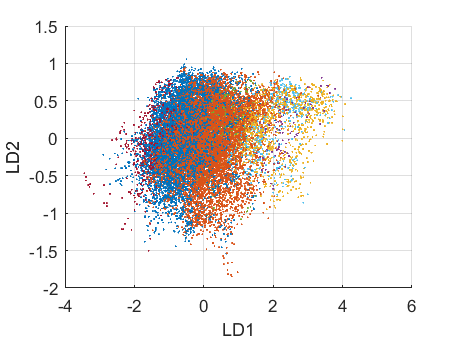


%%2D visualization
figure(10)
xlabel('LD1'); ylabel('LD2'); zlabel('LD3');
grid on
hold on 
view(2)
for k = 1:length(uniqueTarget)
      ind = target == uniqueTarget(k); 
      plot3(proj1(ind),proj2(ind), proj3(ind), '.', 'color', cell2mat(colors(k)), 'markersize',1); 
end

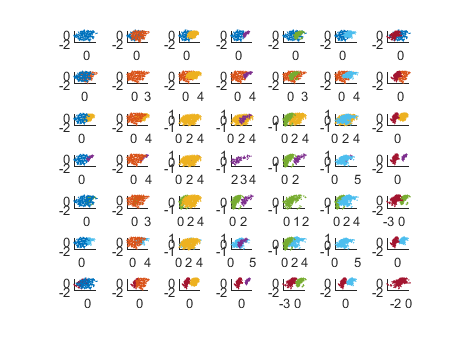


%%pairwise visualization
figure(11)
grid on
hold on

counter = 1;
for k = 1:(length(uniqueTarget))
    ind1 = target ==uniqueTarget(k);
    for j = 1:length(uniqueTarget)
      subplot(7,7,counter);
      ind2 = target == uniqueTarget(j);
      alpha(0.2)
      sz =1;
      scatter(proj1(ind1),proj2(ind1), sz, cell2mat(colors(k)), 'filled');
      hold on
      scatter(proj1(ind2), proj2(ind2), sz, cell2mat(colors(j)), 'filled')
      hold off
      counter = counter +1;
    end
      
end

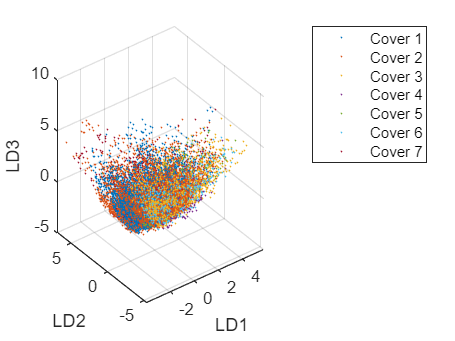

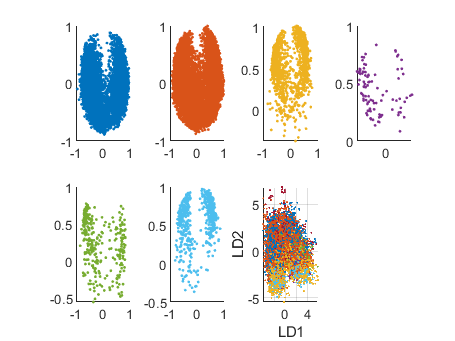

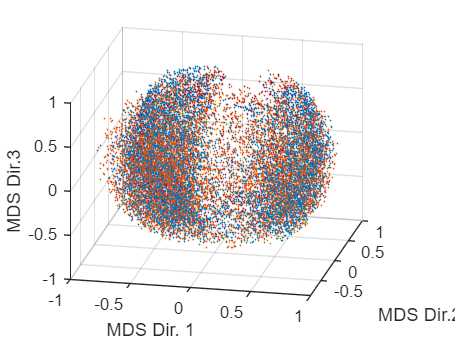

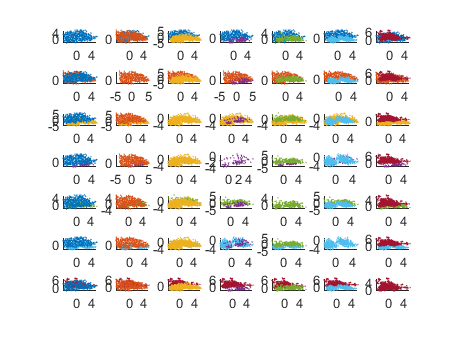

%%we start to get good separation between classes

%%MDS 

%%Dissimilarity matrix with cosine metric
D_mat = pdist(cov_normal,'cosine'); 
%%Conver to square mat
D_mat = squareform(D_mat);
%%Get projection coordinates
[Y,e] = cmdscale(D_mat,3);
%%3D visualization
figure(12)
xlabel('MDS Dir. 1'); ylabel('MDS Dir.2'); zlabel('MDS Dir.3');
grid on
hold on 
view(3)
dir1 = Y(:,1);
dir2 = Y(:,2);
dir3 = Y(:,3);
for k = 1:length(uniqueTarget)
      ind = target == uniqueTarget(k); 
      plot3(dir1(ind),dir2(ind), dir3(ind), '.', 'color', cell2mat(colors(k)), 'markersize',3); 

view([12.38 23.53])
end

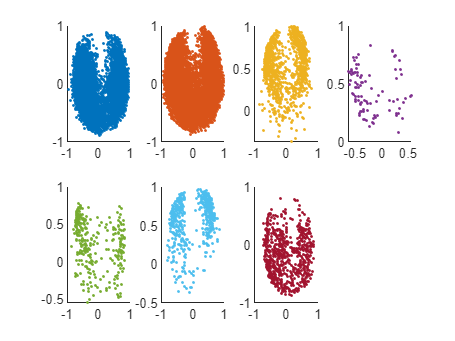


%%2D visualization for each class
figure(13)
grid on
hold on

for k = 1:(length(uniqueTarget))
    subplot(2,4,k)
    sz = 3;
    ind1 = target ==uniqueTarget(k);
    scatter(dir1(ind1),dir2(ind1), sz, cell2mat(colors(k)), 'filled');
end


%%class 1 and class 2 very overrepresented
%%non-linearity apparentD_mat

%%get Kruskal Stress
D_y = squareform(pdist(Y))

D_y =          0    1.0726    1.1177    0.3379    1.1884    0.7688    0.7653    1.1191    0.3755    1.3127    1.1459    1.1952    0.4031    0.6947    0.6334    1.3469    1.1734    1.1360    1.3211    0.9266    0.6880    0.4373    0.3469    0.4322    0.3815    0.8565    0.5131    0.5201    0.9088    1.1969    0.6169    1.0765    1.2837    1.0257    1.2767    0.9508    0.4138    0.7825    0.4103    1.1403    0.8635    0.4874    0.3638    0.4972    0.9415    1.2206    0.4893    0.9985    1.0481    0.4960
    1.0726         0    0.6699    1.3584    0.9459    0.8564    1.1072    0.6646    0.9863    0.9136    0.4736    0.9060    1.0030    1.4237    1.1845    0.3035    1.1351    0.5925    0.4496    0.2288    0.5329    0.9629    1.2703    1.2667    1.2708    0.9421    1.1817    1.4651    0.7513    0.4633    1.0056    0.2899    0.6700    0.0678    0.2226    1.1848    1.4646    1.0669    1.3360    0.0908    1.3818    1.5126    1.3882    1.3649    1.0512    0.8446    1.1438    0.8583    0.2204   

kruskal = norm(D_mat - D_y, "fro")/norm(D_mat,"fro"); %%~0.21


%%correct for symmetry issues 
%%see if this affects Kruskal
DMat_SD = 0.5*(D_mat + D_mat');
[YSD,eSD] = cmdscale(DMat_SD,3);
figure(14)
xlabel('MDS Dir. 1'); ylabel('MDS Dir.2'); zlabel('MDS Dir.3');
grid on
hold on 
view(3)
dir1_sd = YSD(:,1);
dir2_sd = YSD(:,2);
dir3_sd = YSD(:,3);
for k = 1:length(uniqueTarget)
      ind = target == uniqueTarget(k); 
      plot3(dir1_sd(ind),dir2_sd(ind), dir3_sd(ind), '.', 'color', cell2mat(colors(k)), 'markersize',3); 

view([12.38 23.53])
end

figure(15)
grid on
hold on

for k = 1:(length(uniqueTarget))
    subplot(2,4,k)
    sz = 3;
    ind1 = target ==uniqueTarget(k);
    scatter(dir1_sd(ind1),dir2_sd(ind1), sz, cell2mat(colors(k)), 'filled');
end



Dy_SD = squareform(pdist(YSD))

Dy_SD =          0    1.0726    1.1177    0.3379    1.1884    0.7688    0.7653    1.1191    0.3755    1.3127    1.1459    1.1952    0.4031    0.6947    0.6334    1.3469    1.1734    1.1360    1.3211    0.9266    0.6880    0.4373    0.3469    0.4322    0.3815    0.8565    0.5131    0.5201    0.9088    1.1969    0.6169    1.0765    1.2837    1.0257    1.2767    0.9508    0.4138    0.7825    0.4103    1.1403    0.8635    0.4874    0.3638    0.4972    0.9415    1.2206    0.4893    0.9985    1.0481    0.4960
    1.0726         0    0.6699    1.3584    0.9459    0.8564    1.1072    0.6646    0.9863    0.9136    0.4736    0.9060    1.0030    1.4237    1.1845    0.3035    1.1351    0.5925    0.4496    0.2288    0.5329    0.9629    1.2703    1.2667    1.2708    0.9421    1.1817    1.4651    0.7513    0.4633    1.0056    0.2899    0.6700    0.0678    0.2226    1.1848    1.4646    1.0669    1.3360    0.0908    1.3818    1.5126    1.3882    1.3649    1.0512    0.8446    1.1438    0.8583    0.2204 

kruskal_sd = norm(DMat_SD - Dy_SD, "fro")/norm(DMat_SD,"fro"); %%still 0.21

kruskal_sd = 0.2101

%%ISOMAP

%%get random sample of size 5k from our observations
rand_index2 = randi(20000,5000,1);
cov_half = cov_normal(rand_index2,:);
%%make sure our labels are re-indexed too
target2 = target(rand_index2,:);
%%Distance matrix using L2_Distance function
D = L2_distance(cov_half', cov_half',1);

Constructing neighborhood graph...
 Iteration: 50     Estimated time to completion: 0.073996 minutes
 Iteration: 100     Estimated time to completion: 0.0066567 minutes
 Iteration: 150     Estimated time to completion: 0.0094203 minutes
 Iteration: 200     Estimated time to completion: 0.0087277 minutes
 Iteration: 250     Estimated time to completion: 0.0076065 minutes
 Iteration: 300     Estimated time to completion: 0.0084468 minutes
 Iteration: 350     Estimated time to completion: 0.006381 minutes
 Iteration: 400     Estimated time to completion: 0.0059535 minutes
 Iteration: 450     Estimated time to completion: 0.0058307 minutes
 Iteration: 500     Estimated time to completion: 0.0067161 minutes
 Iteration: 550     Estimated time to completion: 0.005564 minutes
 Iteration: 600     Estimated time to completion: 0.0069326 minutes
 Iteration: 650     Estimated time to completion: 0.0055309 minutes
 Iteration: 700     Estimated time to completion: 0.0056101 minutes
 Iteration: 750  

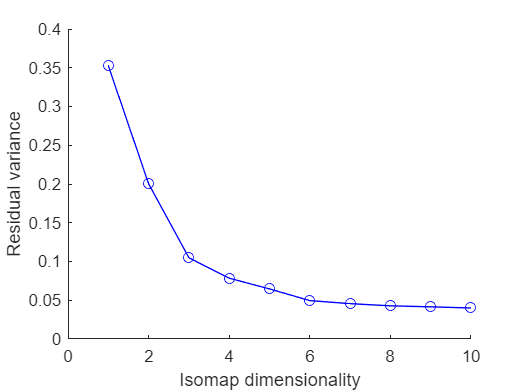

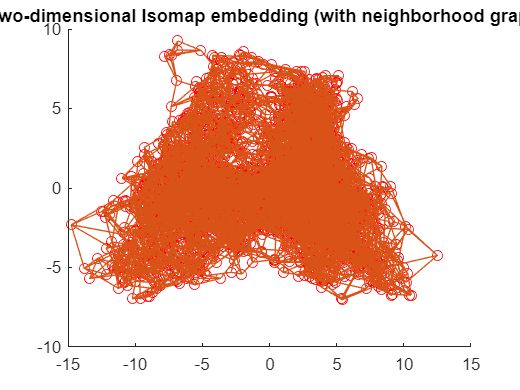

%%Obtain ISOMAP using Djis's algo (faster version)
[Y, R, E] = IsomapII(D, 'k', 5);

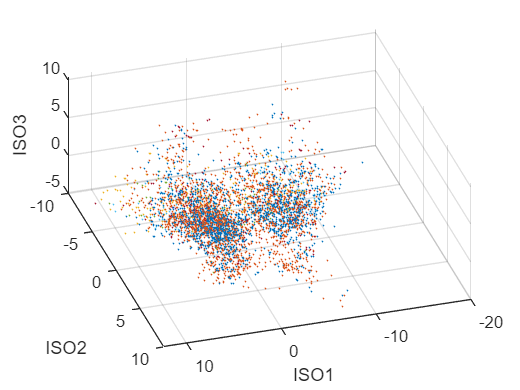

clf
%%get projection axes
Y_full = Y.coords{3}';
Y1 = Y_full(:,1);
Y2 = Y_full(:,2);
Y3 = Y_full(:,3);

%%3D visualization
figure(16)
xlabel('ISO1'); ylabel('ISO2'); zlabel('ISO3');
grid on
hold on 
view([162.8 54.0])
for k = 1:length(uniqueTarget)
      ind = target2 == uniqueTarget(k); 
      plot3(Y1(ind),Y2(ind), Y3(ind), '.', 'color', cell2mat(colors(k)), 'markersize',2); 

end

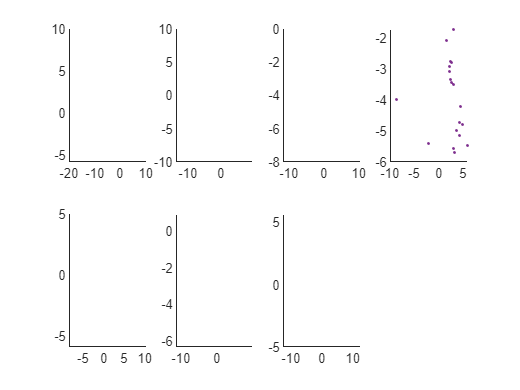


%%2D visualization
figure(17)
grid on
hold on

for k = 1:(length(uniqueTarget))
    subplot(2,4,k)
    sz = 3;
    ind1 = target2 ==uniqueTarget(k);
    scatter(Y1(ind1),Y2(ind1), sz, cell2mat(colors(k)), 'filled');
end